iV = importdata("data.txt")

iV =      1
     5
     7
     9
    11
    15
    17
    19
    23
    23


arr = importdata("settings.txt")

arr =     0.0134
    0.0110


dT = arr(1)

dT = 0.0134

dV = arr(2)

dV = 0.0110

time = 0:dT:(size(iV) * dT - dT)

time =          0    0.0134    0.0268    0.0402    0.0536    0.0670    0.0804    0.0938    0.1072    0.1206    0.1340    0.1474    0.1608    0.1742    0.1876    0.2010    0.2144    0.2278    0.2412    0.2546    0.2680    0.2814    0.2948    0.3082    0.3216    0.3350    0.3484    0.3618    0.3752    0.3886    0.4020    0.4154    0.4288    0.4422    0.4556    0.4690    0.4824    0.4958    0.5092    0.5226    0.5360    0.5494    0.5628    0.5762    0.5896    0.6030    0.6164    0.6298    0.6432    0.6566


aV = iV * dV

aV =     0.0110
    0.0550
    0.0770
    0.0990
    0.1210
    0.1650
    0.1870
    0.2090
    0.2530
    0.2530


[maxV, i] = max(aV)

maxV = 2.7170

i = 384

chargetime = i * dT

chargetime = 5.1456

dischargetime = dT * (size(aV) - i)

dischargetime =     6.8876   -5.1322


plt = plot(time,aV,'--rs',...
    'LineWidth',3,...
    'MarkerSize',10,...
    'MarkerEdgeColor','b', ...
    "MarkerIndices",1:50:size(aV))

plt =   Line with properties:

              Color: [1 0 0]
          LineStyle: '--'
          LineWidth: 3
             Marker: 'square'
         MarkerSize: 10
    MarkerFaceColor: 'none'
              XData: [1×898 double]
              YData: [1×898 double]
              ZData: [1×0 double]

  Show all properties


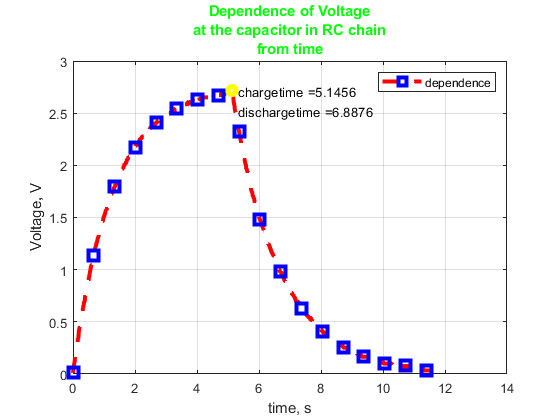


hold on
plot(time(aV == maxV), maxV, "yo",'LineWidth',4)
hold off

grid on

text(time(aV == maxV)+0.2, maxV, "chargetime =" + chargetime)
text(time(aV == maxV)+0.2, maxV-0.2, "dischargetime =" + dischargetime(1))

legend("dependence")
title({'Dependence of Voltage',...
    'at the capacitor in RC chain','from time'},'Color','green')
xlabel('time, s')
ylabel('Voltage, V')

saveas(plt,"Приказчиков, Б03-008.png")
saveas(plt,"Приказчиков, Б03-008.svg")

Из полезных штук, которыми обладает MatLab можно отметить возможность встроенного анализа данных, например можно построить тот же график в логарифмической шкале и по времени заряда - разряда через формулы найти постоянную времени конденсатора RC. Если же знать сопровтивление, то можно будет выразить и ёмкость. Не реализовал нахождение постоянной, потому что не нашёл функцию для апроксимации графика или что-ниудь типо того

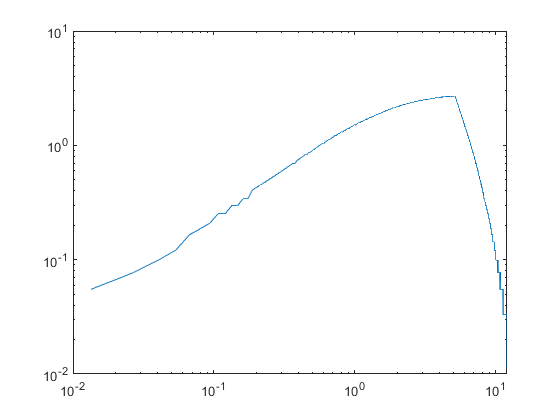

loglog(time,aV)